clc
clear all
close all
rng(0)

# Sampling method for input data

Assesment of the different sample generation methods for input data of the MPC algorithm, in attempt to cover all the input space

- Random uniform

- Random gaussian

- Latin hypercube sampling

- Halton

- Sobol

## Sample generation

n_dims = 27;
n_samples = 10000;

pts_unif = rand(n_dims, n_samples)*2-1;
pts_gauss = randn(n_dims, n_samples)/2; % 2 or 3-sigma rule for max values
pts_lhs = lhsdesign(n_samples, n_dims)'*2-1;
pts_halton = haltonset(n_dims, 'Skip', 100, 'Leap', 10);
pts_halton = net(pts_halton, n_samples)'*2-1;
pts_sobol = sobolset(n_dims, 'Skip', 100, 'Leap', 10);
pts_sobol = net(pts_sobol, n_samples)'*2-1;

## 2D PCA visualization

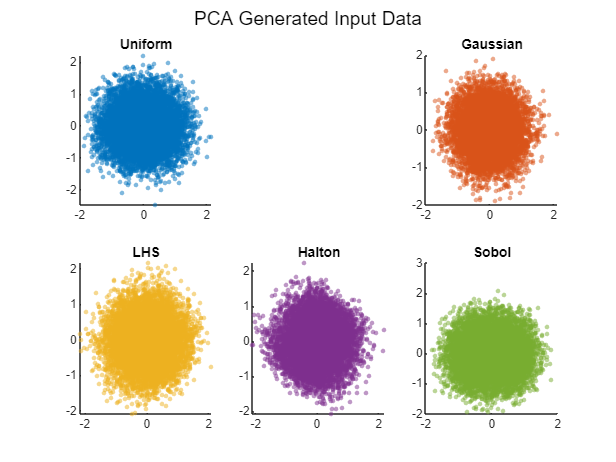

colors = [0.0000 0.4470 0.7410; % Blue
          0.8500 0.3250 0.0980; % Orange
          0.9290 0.6940 0.1250; % Yellow
          0.4940 0.1840 0.5560; % Purple
          0.4660 0.6740 0.1880]; % Green
figure;

% Random uniform
[coeff, score, latent] = pca(pts_unif');
subplot(2, 3, 1);
scatter(score(:, 1), score(:, 2), 10, colors(1, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('Uniform');

% Random gaussian
[coeff, score, latent] = pca(pts_gauss');
subplot(2, 3, 3);
scatter(score(:, 1), score(:, 2), 10, colors(2, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('Gaussian');

% LHS
[coeff, score, latent] = pca(pts_lhs');
subplot(2, 3, 4);
scatter(score(:, 1), score(:, 2), 10, colors(3, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('LHS');

% Halton
[coeff, score, latent] = pca(pts_halton');
subplot(2, 3, 5);
scatter(score(:, 1), score(:, 2), 10, colors(4, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('Halton');

% Sobol
[coeff, score, latent] = pca(pts_sobol');
subplot(2, 3, 6);
scatter(score(:, 1), score(:, 2), 10, colors(5, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('Sobol');

sgtitle('PCA Generated Input Data');

## UMAP

pyenv('Version', '3.12', 'ExecutionMode', 'OutOfProcess')

ans =   PythonEnvironment with properties:

          Version: "3.12"
       Executable: "C:\Users\Ingeniería Eléctrica\AppData\Local\Programs\Python\Python312\pythonw.exe"
          Library: "C:\Users\Ingeniería Eléctrica\AppData\Local\Programs\Python\Python312\python312.dll"
             Home: "C:\Users\Ingeniería Eléctrica\AppData\Local\Programs\Python\Python312"
           Status: Loaded
    ExecutionMode: OutOfProcess
        ProcessID: "10740"
      ProcessName: "MATLABPyHost"

system('pip install umap-learn')

ans = 0

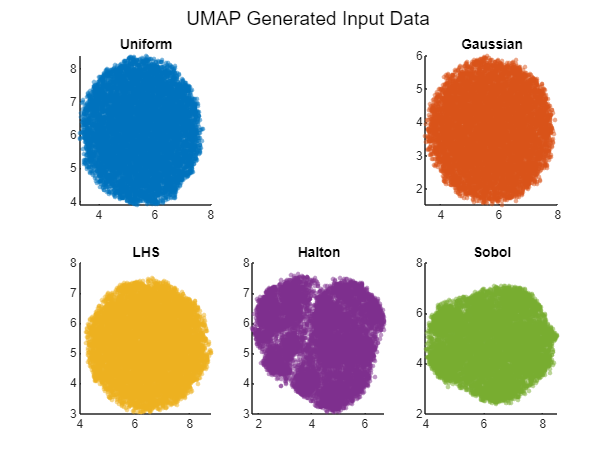


code_X = [
          "import umap"
          "import numpy as np"
          "reducer_X = umap.UMAP(n_neighbors=100, min_dist=0, n_components=2)"
          "Xumap = reducer_X.fit_transform(X)"
         ];

figure;

% Random uniform
Xumap = double(pyrun(code_X, 'Xumap', X=pts_unif'));
subplot(2, 3, 1);
scatter(Xumap(:, 1), Xumap(:, 2), 10, colors(1, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('Uniform');

% Random gaussian
Xumap = double(pyrun(code_X, 'Xumap', X=pts_gauss'));
subplot(2, 3, 3);
scatter(Xumap(:, 1), Xumap(:, 2), 10, colors(2, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('Gaussian');

% LHS
Xumap = double(pyrun(code_X, 'Xumap', X=pts_lhs'));
subplot(2, 3, 4);
scatter(Xumap(:, 1), Xumap(:, 2), 10, colors(3, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('LHS');

% Halton
Xumap = double(pyrun(code_X, 'Xumap', X=pts_halton'));
subplot(2, 3, 5);
scatter(Xumap(:, 1), Xumap(:, 2), 10, colors(4, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('Halton');

% Sobol
Xumap = double(pyrun(code_X, 'Xumap', X=pts_sobol'));
subplot(2, 3, 6);
scatter(Xumap(:, 1), Xumap(:, 2), 10, colors(5, :), 'filled', 'MarkerFaceAlpha', 0.5);
title('Sobol');

sgtitle('UMAP Generated Input Data');

# Space covering evalaution

## KNN for calculation of distances

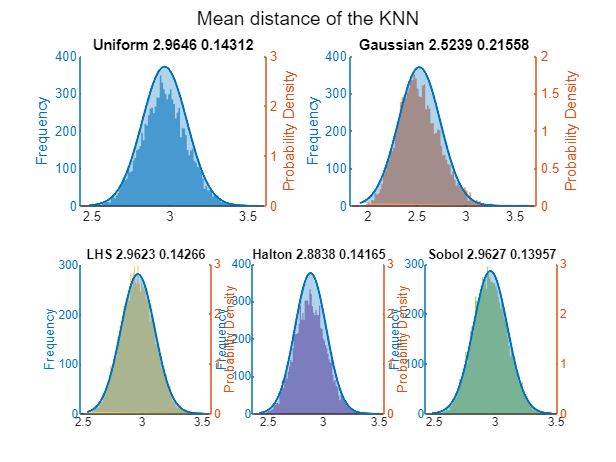

numBins = 100;
k = 100;
figure;

% Random Uniform
[idx, distances] = knnsearch(pts_unif', pts_unif', 'K', k);
distances = distances(:, 2:end);
distances = mean(distances, 2);
subplot(2, 2, 1);
hold on;
yyaxis left;
h = histogram(distances, numBins, 'FaceColor', colors(1, :), 'EdgeColor', 'none');
ylabel('Frequency');
yyaxis right;
mu = mean(distances);
sigma = std(distances);
x = linspace(min(distances), max(distances), 1000);
y = (1 / (sigma * sqrt(2*pi))) * exp(-0.5 * ((x - mu)/sigma).^2);
fill(x, y, colors(1, :), 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x, y, 'Color', colors(1, :), 'LineWidth', 1.5);
ylabel('Probability Density');
title(['Uniform ' num2str(mu) ' ' num2str(sigma)]);
hold off;

% Random Gaussian
[idx, distances] = knnsearch(pts_gauss', pts_gauss', 'K', k);
distances = distances(:, 2:end);
distances = mean(distances, 2);
subplot(2, 2, 2);
hold on;
yyaxis left;
h = histogram(distances, numBins, 'FaceColor', colors(2, :), 'EdgeColor', 'none');
ylabel('Frequency');
yyaxis right;
mu = mean(distances);
sigma = std(distances);
x = linspace(min(distances), max(distances), 1000);
y = (1 / (sigma * sqrt(2*pi))) * exp(-0.5 * ((x - mu)/sigma).^2);
fill(x, y, colors(1, :), 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x, y, 'Color', colors(1, :), 'LineWidth', 1.5);
ylabel('Probability Density');
title(['Gaussian ' num2str(mu) ' ' num2str(sigma)]);
hold off;

% LHS
[idx, distances] = knnsearch(pts_lhs', pts_lhs', 'K', k);
distances = distances(:, 2:end);
distances = mean(distances, 2);
subplot(2, 3, 4);
hold on;
yyaxis left;
h = histogram(distances, numBins, 'FaceColor', colors(3, :), 'EdgeColor', 'none');
ylabel('Frequency');
yyaxis right;
mu = mean(distances);
sigma = std(distances);
x = linspace(min(distances), max(distances), 1000);
y = (1 / (sigma * sqrt(2*pi))) * exp(-0.5 * ((x - mu)/sigma).^2);
fill(x, y, colors(1, :), 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x, y, 'Color', colors(1, :), 'LineWidth', 1.5);
ylabel('Probability Density');
title(['LHS ' num2str(mu) ' ' num2str(sigma)]);
hold off;

% Halton
[idx, distances] = knnsearch(pts_halton', pts_halton', 'K', k);
distances = distances(:, 2:end);
distances = mean(distances, 2);
subplot(2, 3, 5);
hold on;
yyaxis left;
h = histogram(distances, numBins, 'FaceColor', colors(4, :), 'EdgeColor', 'none');
ylabel('Frequency');
yyaxis right;
mu = mean(distances);
sigma = std(distances);
x = linspace(min(distances), max(distances), 1000);
y = (1 / (sigma * sqrt(2*pi))) * exp(-0.5 * ((x - mu)/sigma).^2);
fill(x, y, colors(1, :), 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x, y, 'Color', colors(1, :), 'LineWidth', 1.5);
ylabel('Probability Density');
title(['Halton ' num2str(mu) ' ' num2str(sigma)]);
hold off;

% Sobol
[idx, distances] = knnsearch(pts_sobol', pts_sobol', 'K', k);
distances = distances(:, 2:end);
distances = mean(distances, 2);
subplot(2, 3, 6);
hold on;
yyaxis left;
h = histogram(distances, numBins, 'FaceColor', colors(5, :), 'EdgeColor', 'none');
ylabel('Frequency');
yyaxis right;
mu = mean(distances);
sigma = std(distances);
x = linspace(min(distances), max(distances), 1000);
y = (1 / (sigma * sqrt(2*pi))) * exp(-0.5 * ((x - mu)/sigma).^2);
fill(x, y, colors(1, :), 'FaceAlpha', 0.3, 'EdgeColor', 'none');
plot(x, y, 'Color', colors(1, :), 'LineWidth', 1.5);
title(['Sobol ' num2str(mu) ' ' num2str(sigma)]);
hold off;

sgtitle('Mean distance of the KNN');

## Correlation between samples

correlation = corrcoef(pts_unif');
correlation = correlation - diag(diag(correlation)); % Take out autocorrelation
mean(correlation(:))

ans = 0.0017

std(correlation(:))

ans = 0.0094


correlation = corrcoef(pts_gauss');
correlation = correlation - diag(diag(correlation));
mean(correlation(:))

ans = 3.3660e-04

std(correlation(:))

ans = 0.0102


correlation = corrcoef(pts_lhs');
correlation = correlation - diag(diag(correlation));
mean(correlation(:))

ans = 6.4019e-04

std(correlation(:))

ans = 0.0101


correlation = corrcoef(pts_halton');
correlation = correlation - diag(diag(correlation));
mean(correlation(:))

ans = -8.3712e-05

std(correlation(:))

ans = 0.0012


correlation = corrcoef(pts_sobol');
correlation = correlation - diag(diag(correlation));
mean(correlation(:))

ans = -5.3282e-04

std(correlation(:))

ans = 0.0078

## Entropy

d = size(X, 1);

X = pts_unif;
differential_entropy(X')

ans = 18.9025


X = pts_gauss;
differential_entropy(X')

ans = 19.7866


X = pts_lhs;
differential_entropy(X')

ans = 23.3977


X = pts_halton;
differential_entropy(X')

ans = 20.2404


X = pts_sobol;
differential_entropy(X')

ans = 19.6383

Greater entropy -> better space coverage

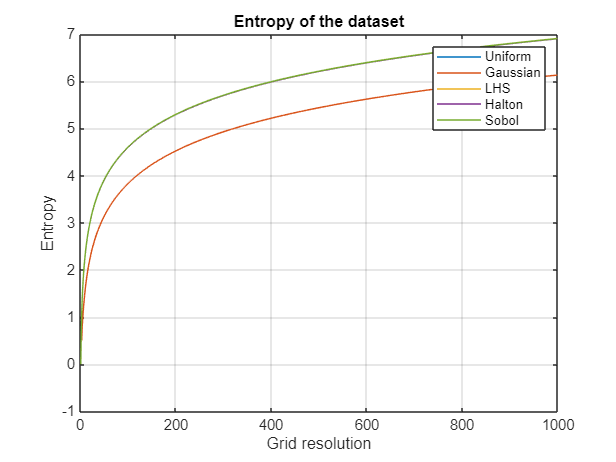

H_list = [];
max_numBins = 1000;

figure

X = pts_unif;
for numBins = 2:max_numBins
edges = linspace(min(X(:)), max(X(:)), numBins);
counts = histcounts(X, edges, 'Normalization', 'probability');
H_list(numBins-1) = -sum(counts .* log(counts + eps));
end
plot(H_list)
hold on

X = pts_gauss;
for numBins = 2:max_numBins
edges = linspace(min(X(:)), max(X(:)), numBins);
counts = histcounts(X, edges, 'Normalization', 'probability');
H_list(numBins-1) = -sum(counts .* log(counts + eps));
end
plot(H_list)

X = pts_lhs;
for numBins = 2:max_numBins
edges = linspace(min(X(:)), max(X(:)), numBins);
counts = histcounts(X, edges, 'Normalization', 'probability');
H_list(numBins-1) = -sum(counts .* log(counts + eps));
end
plot(H_list)

X = pts_halton;
for numBins = 2:max_numBins
edges = linspace(min(X(:)), max(X(:)), numBins);
counts = histcounts(X, edges, 'Normalization', 'probability');
H_list(numBins-1) = -sum(counts .* log(counts + eps));
end
plot(H_list)

X = pts_sobol;
for numBins = 2:max_numBins
edges = linspace(min(X(:)), max(X(:)), numBins);
counts = histcounts(X, edges, 'Normalization', 'probability');
H_list(numBins-1) = -sum(counts .* log(counts + eps));
end
plot(H_list)

hold off
grid on
legend('Uniform', 'Gaussian', 'LHS', 'Halton', 'Sobol')
xlabel('Grid resolution')
ylabel('Entropy')
title('Entropy of the dataset')